# Calculating the averages

In the following file the different success, failure and clarification averages that are needed for the report is being calculated

## How many does Config 5 fail more than Config 4?

% Define the total number of examples for navigation and locate
total_examples_for_navigation = 10 * 100; 
total_examples_for_locate = 12 * 100; 

% Define the number of fails for config4 and config5 for navigation
config4_fails_navigations = sum([5, 1, 5, 2, 11, 22, 5, 69, 100, 1]);
config5_fails_navigations = sum([6, 3, 1, 5, 18, 5, 52, 100, 0, 0]);

% Define the number of fails for config4 and config5 for locate
config4_fails_locate = sum([32, 33, 77, 0, 13, 46, 0, 1, 3, 7, 0, 100]);
config5_fails_locate = sum([68, 27, 85, 21, 32, 49, 5, 28, 74, 28, 3, 100]);

% Calculate the difference in fails between config5 and config4 for navigation and locate
diff_fails_navigation = config5_fails_navigations - config4_fails_navigations;
diff_fails_locate = config5_fails_locate - config4_fails_locate;

% Calculate the difference in fails between config5 and config4 for navigation and locate
diff_fails_navigation = config5_fails_navigations - config4_fails_navigations;
diff_fails_locate = config5_fails_locate - config4_fails_locate;

% Calculate the difference in fails between config5 and config4 for navigation and locate
diff_fails_navigation = config5_fails_navigations - config4_fails_navigations;
diff_fails_locate = config5_fails_locate - config4_fails_locate;

% Calculate the percentage difference in fails
percent_diff_navigation = (diff_fails_navigation / config4_fails_navigations) * 100;
percent_diff_locate = (diff_fails_locate / config4_fails_locate) * 100;

% Calculate total fails for each configuration
total_fails_config4 = config4_fails_navigations + config4_fails_locate;
total_fails_config5 = config5_fails_navigations + config5_fails_locate;

% Calculate the total number of examples
total_examples = total_examples_for_navigation + total_examples_for_locate;

% Calculate the overall percentage difference in fails
overall_diff_fails = total_fails_config5 - total_fails_config4;
percent_diff_overall = (overall_diff_fails / total_fails_config4) * 100;

% Display the results
disp(['Config5 fails ', num2str(diff_fails_navigation), ' more times than Config4 for navigation.']);

Config5 fails -31 more times than Config4 for navigation.


disp(['This is ', num2str(percent_diff_navigation), '% worse.']);

This is -14.0271% worse.


disp(['Config5 fails ', num2str(diff_fails_locate), ' more times than Config4 for locate.']);

Config5 fails 208 more times than Config4 for locate.


disp(['This is ', num2str(percent_diff_locate), '% worse.']);

This is 66.6667% worse.


disp(['Overall, Config5 fails ', num2str(overall_diff_fails), ' more times than Config4.']);

Overall, Config5 fails 177 more times than Config4.


disp(['This is ', num2str(percent_diff_overall), '% worse overall.']);

This is 33.2083% worse overall.


## Success rate of configuration 6

% Define the total number of examples for navigation and locate
total_examples_for_navigation = 10 * 100; 
total_examples_for_locate = 12 * 100; 

config6_success_navigations =sum([96,100,99,100,91,84,100,48,0,99])

config6_success_navigations = 817

config6_success_failure =sum([52,59,12,100,77,96,99,97,100,9,100,0])

config6_success_failure = 801


% Define the total number of examples for navigation and locate
total_examples_for_navigation = 10 * 100; 
total_examples_for_locate = 12 * 100; 

% Define the number of successes for config6 for navigation and locate
config6_success_navigations = sum([96, 100, 99, 100, 91, 84, 100, 48, 0, 99]);
config6_success_locate = sum([52, 59, 12, 100, 77, 96, 99, 97, 100, 9, 100, 0]);

% Calculate the total number of successes
total_successes_config6 = config6_success_navigations + config6_success_locate;

% Calculate the combined total number of examples
total_examples = total_examples_for_navigation + total_examples_for_locate;

% Calculate the overall success rate
success_rate_overall = (total_successes_config6 / total_examples) * 100;

% Display the results
disp(['Config6 has a total of ', num2str(total_successes_config6), ' successes out of ', num2str(total_examples), ' examples.']);

Config6 has a total of 1618 successes out of 2200 examples.


disp(['The overall success rate is ', num2str(success_rate_overall), '%.']);

The overall success rate is 73.5455%.


## Average successrate accross multiple level 2

% Define the total number of examples
number_of_examples = 15 * 200;

% Define the successes from multiple runs
success = sum([130, 159, 172, 144, 153, 158, 157, 161, 151, 168, 167, 163, 174, 181]);

% Calculate the overall success rate
success_rate = (success / number_of_examples) * 100;

% Display the results
disp(['The total number of successes is ', num2str(success), ' out of ', num2str(number_of_examples), ' examples.']);

The total number of successes is 2238 out of 3000 examples.


disp(['The overall success rate is ', num2str(success_rate), '%.']);

The overall success rate is 74.6%.


## Calculate the decrease successrate accross multiple level 2

% Define the total number of examples
number_of_examples = 13 * 200;

% Define the successes from multiple runs
list_of_success = [121, 89, 92, 80, 85, 71, 69, 59, 53, 46, 48, 51];

% Calculate the success rate for each value in the list
success_rates = (list_of_success / number_of_examples) * 100;

% Define the run numbers (1 to the number of successes)
run_numbers = 1:length(success_rates);

% Perform linear regression
coefficients = polyfit(run_numbers, list_of_success, 1);

% Extract the slope (rate of decrease) and intercept from the coefficients
slope = coefficients(1);
intercept = coefficients(2);

% Calculate the fitted values
fitted_values = polyval(coefficients, run_numbers);

% Display the results
disp(['The slope of the linear regression line is ', num2str(slope), ' which indicates the average rate of change in success rate.']);

The slope of the linear regression line is -5.8601 which indicates the average rate of change in success rate.


disp(['The intercept of the linear regression line is ', num2str(intercept), '.']);

The intercept of the linear regression line is 110.0909.


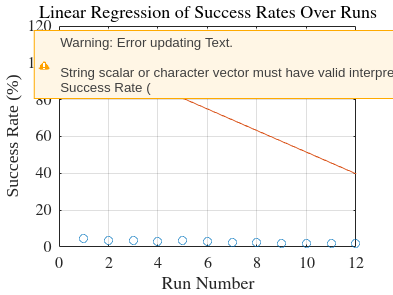


% Plot the original success rates and the fitted line
figure;
plot(run_numbers, success_rates, 'o', 'DisplayName', 'Original Success Rates');
hold on;
plot(run_numbers, fitted_values, '-', 'DisplayName', 'Fitted Line');
xlabel('Run Number');
ylabel('Success Rate (%)');
title('Linear Regression of Success Rates Over Runs');
legend show;
grid on;

## Calculate the increase successrate of GPT-4o

% Define the total number of examples for navigation and locate
GPT4total_examples_for_navigation = 10 * 100; 
GPT4total_examples_for_locate = 12 * 100; 

% Define the number of successes for config6 for navigation and locate
GPT4config6_success_navigations = sum([100,98,99,100,100,100,100,99,100,100]);
GPT4config6_success_locate = sum([84,66,88,98,99,100,100,100,99,100,100]);

% Calculate the total number of successes
GPT4total_successes_config6 = GPT4config6_success_navigations + GPT4config6_success_locate;

% Calculate the combined total number of examples
GPT4total_examples = GPT4total_examples_for_navigation + GPT4total_examples_for_locate;

% Calculate the overall success rate
GPT4success_rate_overall = (GPT4total_successes_config6 / GPT4total_examples) * 100;

% Display the results
disp(['GPT4Config6 has a total of ', num2str(GPT4total_successes_config6), ' successes out of ', num2str(total_examples), ' examples.']);

GPT4Config6 has a total of 2030 successes out of 2200 examples.


disp(['The overall success rate is ', num2str(GPT4success_rate_overall), '%.']);

The overall success rate is 92.2727%.





%GPT4config4_success_navigations = sum([100,99,99,100,100,100,100,97,99,100]);
%GPT4config4_success_locate = sum([98,100,96,100,100,98,100,100,99,100,100]);


## Calculate the average successrate across the level 2 for GPT-4o to determine the increase from previous

% Define the total number of examples
number_of_examples = 19 * 200;

% Define the successes from multiple runs
success = sum([199,192,194,186,185,188,187,189,192,186,188,188,191,185,185,191,184,181]);

% Calculate the overall success rate
success_rate = (success / number_of_examples) * 100;

% Display the results
disp(['The total number of successes is ', num2str(success), ' out of ', num2str(number_of_examples), ' examples.']);

The total number of successes is 3391 out of 3800 examples.


disp(['The overall success rate is ', num2str(success_rate), '%.']);

The overall success rate is 89.2368%.
